clear all

%FORWARD KINEMATICS
syms theta1 theta2 theta3 theta4 theta5 theta6 ;

alpha = [90 0 0 -90 90 0] ; 
a = [0 40 30 0 0 0] ; 
d = [0 0 0 10 10 50] ;
theta = [theta1 theta2 theta3 theta4 theta5 theta6 ]

$$theta = \left(\begin{array}{cccccc} \theta_{1} & \theta_{2} & \theta_{3} & \theta_{4} & \theta_{5} & \theta_{6} \end{array}\right)$$



T0_1 = T_matrix(theta1,alpha(1),a(1),d(1)) ;
T1_2 = T_matrix(theta2,alpha(2),a(2),d(2)) ;
T2_3 = T_matrix(theta3,alpha(3),a(3),d(3)) ;
T3_4 = T_matrix(theta4,alpha(4),a(4),d(4)) ;
T4_5 = T_matrix(theta5,alpha(4),a(4),d(4)) ;
T5_6 = T_matrix(theta6,alpha(5),a(5),d(5)) ;
T0_6 = T0_1*T1_2*T2_3*T3_4*T4_5*T5_6 ;




%INVERSE KINEMATICS
pd = [2.8 ; 57.01 ; 22.2] %desired position 

pd =     2.8000
   57.0100
   22.2000


od = [2.6 ; 1.1 ; -2.22] %desired orientation

od =     2.6000
    1.1000
   -2.2200



roll = atan2(T0_6(2,1),T0_6(1,1)) ;
pitch = atan2(-T0_6(3,1),sqrt((T0_6(3,2))^2 + (T0_6(3,3))^2)) ;
yaw = atan2(T0_6(3,2),T0_6(3,3)) ;

J = jacobian([T0_6(1,4),T0_6(2,4),T0_6(3,4),roll,pitch,yaw],[theta1,theta2,theta3,theta4,theta5,theta6])


K = 0.02 %update constant

K = 0.0200



%random values for thetas
theta1 = 30*randn(1,1)

theta1 = -12.9062

theta2 = 30*randn(1,1)

theta2 = -48.8197

theta3 = 30*randn(1,1)

theta3 = 4.9904

theta4 = 30*randn(1,1)

theta4 = 11.2880

theta5 = 30*randn(1,1)

theta5 = -6.8085

theta6 = 30*randn(1,1)

theta6 = -34.4674


pc = T0_6(1:3,4) ; %calculated position
oc =  [roll;pitch;yaw] ;  %calculated orientation 

delta_x = vertcat(pd-pc, od-oc) ;
q = [theta1 ; theta2 ; theta3 ; theta4 ; theta5 ; theta6 ] ;
q = vpa(subs(q),3) ;
A = [] ;
B = [] ;
for i = 1:500 
    Ji = inv(vpa(subs(J),2)) ;
    deltaa_x = vpa(subs(delta_x),2) ;
    qnew = q + K*(Ji)*deltaa_x ;
    q = qnew ;
    theta1 = q(1);
    theta2 = q(2);
    theta3 = q(3);
    theta4 = q(4);
    theta5 = q(5);
    theta6 = q(6);
    A = [A,norm(deltaa_x)] ;
    B = [B,i];
end
deltaa_x

$$deltaa\_x = \left(\begin{array}{c} -3.8e-3\\ 7.9e-3\\ 3.1e-3\\ -5.0e-6\\ 8.3e-5\\ -9.2e-7 \end{array}\right)$$

q = vpa(q,3) 

$$q = \left(\begin{array}{c} -8.12\\ -54.3\\ 1.28\\ 27.5\\ -12.0\\ -42.3 \end{array}\right)$$

plot(B,A)
f = gcf

f =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [573 438 560 420]
       Units: 'pixels'

  Show all properties


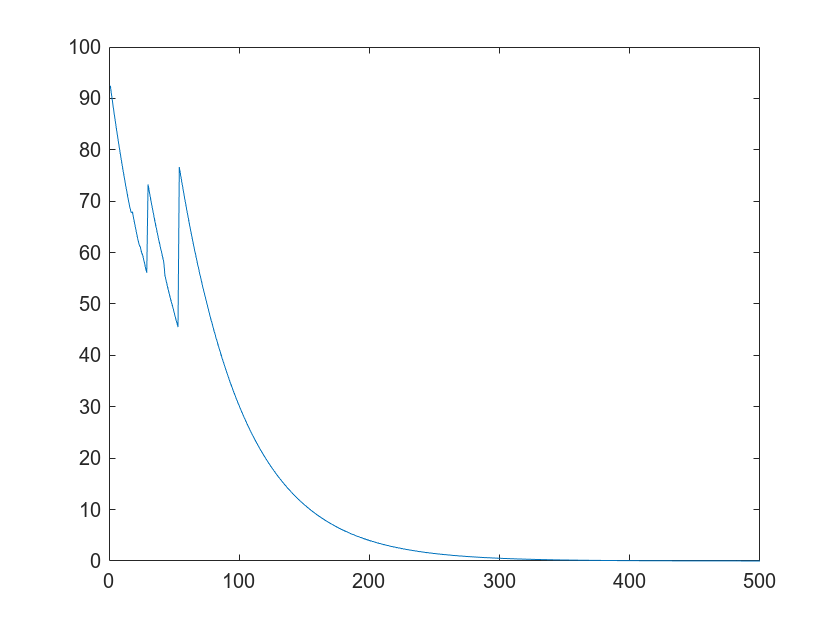

exportgraphics(f, "IK_Jacobian.jpg", "Resolution", 400);

alpha = [90 0 0 -90 90 0] ; 
a = [0 40 30 0 0 0] ; 
d = [0 0 0 10 10 50] ;
theta = [theta1 theta2 theta3 theta4 theta5 theta6 ] ;
theta = double(theta)

theta =    -8.1158  -54.3378    1.2825   27.4827  -11.9909  -42.2927


dhparams= transpose([a/100 ; alpha; d/100 ; theta]) ;


%VISUALSATION
robot = rigidBodyTree

robot =   rigidBodyTree with properties:

     NumBodies: 0
        Bodies: {1×0 cell}
          Base: [1×1 rigidBody]
     BodyNames: {1×0 cell}
      BaseName: 'base'
       Gravity: [0 0 0]
    DataFormat: 'struct'


body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');

setFixedTransform(jnt1,dhparams(1,:),'dh');
body1.Joint = jnt1;

addBody(robot,body1,'base')

body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute');
body3 = rigidBody('body3');
jnt3 = rigidBodyJoint('jnt3','revolute');
body4 = rigidBody('body4');
jnt4 = rigidBodyJoint('jnt4','revolute');
body5 = rigidBody('body5');
jnt5 = rigidBodyJoint('jnt5','revolute');
body6 = rigidBody('body6');
jnt6 = rigidBodyJoint('jnt6','revolute');

setFixedTransform(jnt2,dhparams(2,:),'dh');
setFixedTransform(jnt3,dhparams(3,:),'dh');
setFixedTransform(jnt4,dhparams(4,:),'dh');
setFixedTransform(jnt5,dhparams(5,:),'dh');
setFixedTransform(jnt6,dhparams(6,:),'dh');

body2.Joint = jnt2;
body3.Joint = jnt3;
body4.Joint = jnt4;
body5.Joint = jnt5;
body6.Joint = jnt6;

addBody(robot,body2,'body1')
addBody(robot,body3,'body2')
addBody(robot,body4,'body3')
addBody(robot,body5,'body4')
addBody(robot,body6,'body5')

showdetails(robot) ;

--------------------
Robot: (6 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3     revolute            body2(2)   body4(4)  
   4        body4         jnt4     revolute            body3(3)   body5(5)  
   5        body5         jnt5     revolute            body4(4)   body6(6)  
   6        body6         jnt6     revolute            body5(5)   
--------------------


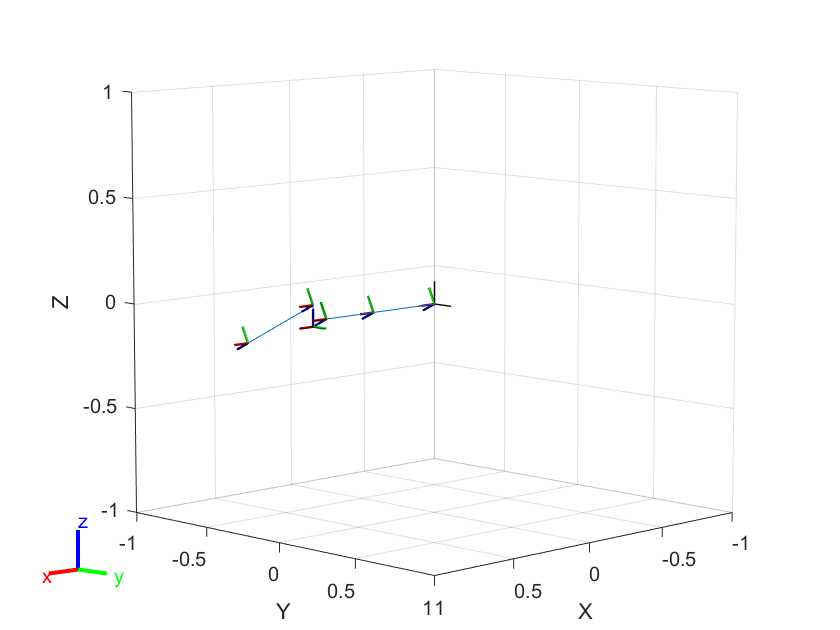

ax = show(robot, 'Frames', 'on') ;

function T = T_matrix(theta,alpha,a,d) 
    T = [cos(theta) -cos(alpha)*sin(theta) sin(alpha)*sin(theta) a*cos(theta) ;
        sin(theta) cos(alpha)*cos(theta) -sin(alpha)*cos(theta) a*sin(theta) ;
        0 sin(alpha) cos(alpha) d ;
        0 0 0 1] ;
end